Min: 0.00 TECU


Max: 85.21 TECU


Mean: 14.46 TECU


Hour 23: 19708 bins occupied (from 376065 raw points)



=== Hour 23 GNSS TEC Statistics by Longitude Bin ===


Lon Bin                  Mean   Median      P90      Max      N


----------------------------------------------------------


-180 to -90              20.5     17.1     39.0     85.2   4281
-90 to 0                 16.3     15.2     32.3     79.9   5748
0 to 90                   6.8      6.0     11.6     26.0   4862
90 to 180                14.7     12.6     26.8     48.0   4817


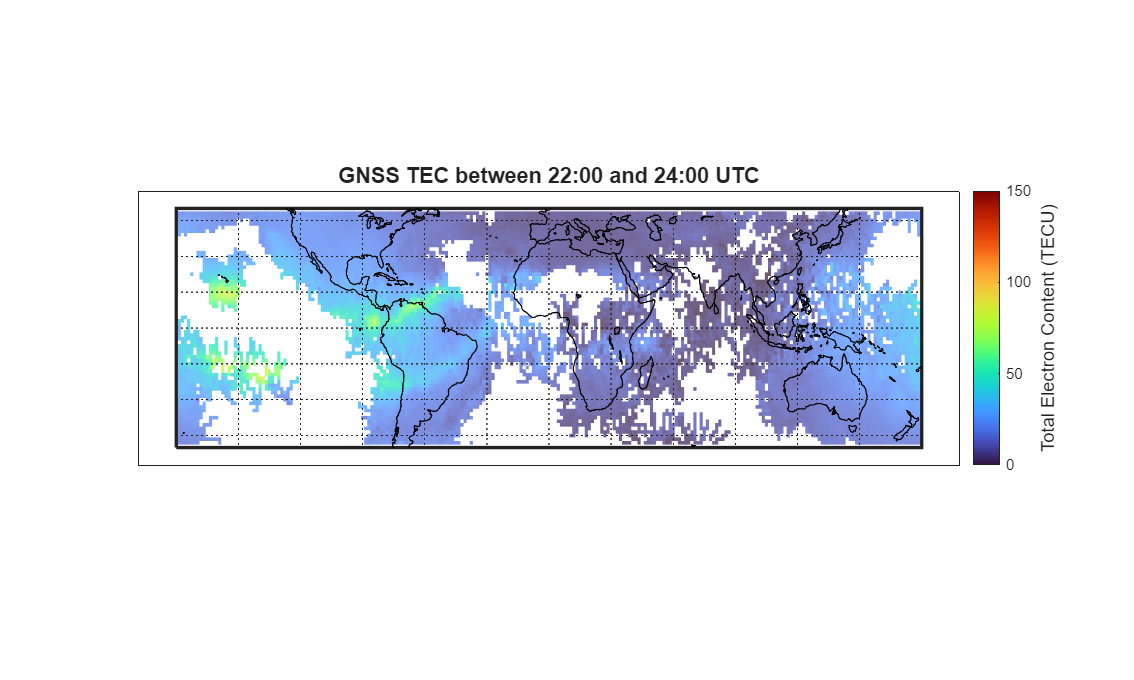

%% Madrigal GNSS TEC Map
clear min

% hyperparameters
filter_quartiles = false;
lower_pct        = 25;
upper_pct        = 75;
hdf5_file        = 'gps260109g.001.hdf5';

% store the data

data = load('gnss_tec.mat');
lat  = double(data.lat);
lon  = double(data.lon);
tec  = double(data.tec);
hr   = double(data.hour);
mn   = double(data.min);

%replace missing values
tec(tec <= 0) = NaN;

for target_hour = 23
    target_minute  = 00;
    time_tolerance = 60;
    minHour = target_hour - (time_tolerance/60);
    maxHour = target_hour + (time_tolerance/60);

    %Time filter
    file_total_minutes   = hr * 60 + mn;
    target_total_minutes = target_hour * 60 + target_minute;
    time_mask = abs(file_total_minutes - target_total_minutes) <= time_tolerance;

    all_lat = lat(time_mask);
    all_lon = lon(time_mask);
    all_tec = tec(time_mask);

    %Remove NaNs
    valid = ~isnan(all_lat) & ~isnan(all_lon) & ~isnan(all_tec);
    all_lat = all_lat(valid);
    all_lon = all_lon(valid);
    all_tec = all_tec(valid);

    if isempty(all_lat)
        warning('No points found for hour %02d', target_hour);
        continue
    end

    %Quartile filter
    if filter_quartiles
        q_low  = prctile(all_tec, lower_pct);
        q_high = prctile(all_tec, upper_pct);
        keep   = all_tec >= q_low & all_tec <= q_high;
        all_lat = all_lat(keep);
        all_lon = all_lon(keep);
        all_tec = all_tec(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f-%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after filter for hour %02d.', target_hour);
        continue
    end

    %Spatial Grid Binning
    bin_size = 1.5;

    bin_lat_idx = floor(all_lat / bin_size) * bin_size + bin_size/2;
    bin_lon_idx = floor(all_lon / bin_size) * bin_size + bin_size/2;

    valid = ~isnan(bin_lat_idx) & ~isnan(bin_lon_idx) & ...
            all_lat >= -90 & all_lat <= 90 & ...
            all_lon >= -180 & all_lon <= 180;

    bin_lat_idx   = bin_lat_idx(valid);
    bin_lon_idx   = bin_lon_idx(valid);
    all_tec_valid = all_tec(valid);

    [G, bin_lat, bin_lon] = findgroups(bin_lat_idx, bin_lon_idx);
    bin_tec = splitapply(@mean, all_tec_valid, G);

    all_lat = bin_lat;
    all_lon = bin_lon;
    cdata   = bin_tec;
    fprintf('Min: %.2f TECU\n', min(cdata))
    fprintf('Max: %.2f TECU\n', max(cdata))
    fprintf('Mean: %.2f TECU\n', mean(cdata))
    fprintf('Hour %02d: %d bins occupied (from %d raw points)\n', ...
        target_hour, length(cdata), sum(valid));

    %90 degree Longitude Bin Statistics
    lon_edges  = [-180, -90, 0, 90, 180];
    lon_labels = {'-180 to -90', '-90 to 0', '0 to 90', '90 to 180'};
    lon_bin    = discretize(all_lon, lon_edges);

    valid_bins = ~isnan(lon_bin);
    lon_bin_v  = lon_bin(valid_bins);
    cdata_v    = cdata(valid_bins);
    
    [G2, grp_lon] = findgroups(lon_bin_v);
    grp_mean   = splitapply(@mean,   cdata_v, G2);
    grp_median = splitapply(@median, cdata_v, G2);
    grp_p90    = splitapply(@(x) prctile(x, 90), cdata_v, G2);
    grp_max    = splitapply(@max,    cdata_v, G2);
    grp_count  = splitapply(@numel,  cdata_v, G2);

    fprintf('\n=== Hour %02d GNSS TEC Statistics by Longitude Bin ===\n', target_hour);
    fprintf('%-20s %8s %8s %8s %8s %6s\n', 'Lon Bin', 'Mean', 'Median', 'P90', 'Max', 'N');
    fprintf('%s\n', repmat('-', 1, 58));
    for g = 1:length(grp_mean)
        fprintf('%-20s %8.1f %8.1f %8.1f %8.1f %6d\n', ...
            lon_labels{grp_lon(g)}, ...
            grp_mean(g), grp_median(g), grp_p90(g), grp_max(g), grp_count(g));
    end
    fprintf('\n');
%Figure
    figure('Color', 'w', 'Position', [100 100 1000 600]);
    clf
    axesm('eqdcylin', 'MapLatLimit', [-50 50], 'MapLonLimit', [-180 180], ...
          'Frame', 'on', 'Grid', 'on')
    hold on


    lat_vec = unique(all_lat);
    lon_vec = unique(all_lon);
    TEC_grid = NaN(length(lat_vec), length(lon_vec));
    for k = 1:length(all_lat)
        i = find(lat_vec == all_lat(k));
        j = find(lon_vec == all_lon(k));
        TEC_grid(i,j) = cdata(k);
    end
    pcolorm(lat_vec, lon_vec, TEC_grid);
    shading flat
    alpha(0.7)
    
    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)

    colormap("turbo")
    cb = colorbar;
    clim([0, 150])
    cb.Label.String   = 'Total Electron Content (TECU)';
    cb.Label.FontSize = 11;
    title(sprintf('GNSS TEC between %02d:%02d and %02d:%02d UTC', ...
        minHour, target_minute, maxHour, target_minute), ...
        'FontSize', 13, 'FontWeight', 'bold')
end